%Stellar Motion Project by Nandni

load starData
nObs = size(spectra,1)

nObs = 357

lambdaStart = 630.02

lambdaStart = 630.0200

lambdaDelta = 0.14

lambdaDelta = 0.1400


%Creating a variable named lambdaEnd (λend) that contains the value of the last wavelength in the recorded spectrum. 
% I am using equation λstart+(nObs−1)λdelta to calculate lambdaEnd

lambdaEnd = lambdaStart + (nObs-1)*lambdaDelta

lambdaEnd = 679.8600

lambda = (lambdaStart:lambdaDelta:lambdaEnd)'

lambda =   630.0200
  630.1600
  630.3000
  630.4400
  630.5800
  630.7200
  630.8600
  631.0000
  631.1400
  631.2800



%performing the red shift calculation on the second star in spectra
s = spectra(:,2)

s = 	1.0e+-12 *

    0.1340
    0.1338
    0.1347
    0.1357
    0.1354
    0.1343
    0.1335
    0.1325
    0.1335
    0.1329


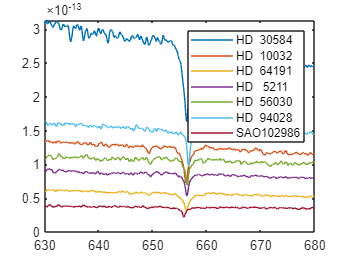


plot(lambda,spectra)
legend(starnames)



%Plotting the spectra (s) as a function of wavelength (lambda). Using point markers (.) and a solid line (-) connecting the points.
%Adding the x-label "Wavelength" and the y-label "Intensity" to the plot.
loglog(lambda,s,".-")
xlabel("Wavelength")
ylabel("Intensity")
%Creating two variables, sHa and idx that contain the minimum value of s and the index where the minimum value occurred.
%Using idx to index into lambda to find the wavelength of the Hydrogen-alpha line. Storing the result as lambdaHa (λHa).
[sHa,idx] = min(s)

sHa = 7.2400e-14

idx = 187

lambdaHa = lambda(idx)

lambdaHa = 656.0600

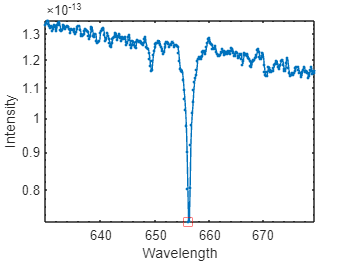

%Adding a point to the existing graph by plotting x = lambdaHa, y = sHa as a red square ("rs") with a marker size ("MarkerSize") of 8.
hold on
loglog(lambdaHa,sHa,"rs","MarkerSize",8)
hold off


%Calculating the redshift factor (z) and the speed (in km/s) at which the star is moving away from the earth. Assigning the redshift factor to a variable called z and the speed to a variable called speed.
z = lambdaHa/656.28 - 1

z = -3.3522e-04

speed = z*299792.458

speed = -100.4973


load starData

%calculating the speed of all the stars
[sHa,idx] = min(spectra);
lambdaHa = lambda(idx);
z = lambdaHa/656.28 - 1;
speed = z*299792.458

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


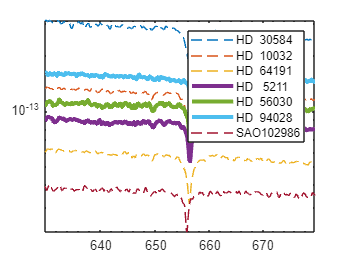


% plotting the spectra of all seven stars using different line properties for redshifted and blueshifted spectra. It is convenient to use a for loop to access each star's data one at a time. 
% plotting the blueshifted spectra using dashed lines.If speed(v) is less than or equal to 0, creating a plot of s against lambda using a dashed line (--). 
% plotting the redshifted spectra using a thick line If speed(v) is greater than 0, creating a plot of s against lambda using a line width of 3.
for c = 1:7
    s = spectra(:,c);

    if speed(c) <= 0
        loglog(lambda,s,"--")
    else
       loglog(lambda,s,"LineWidth",3) 
    end
    hold on
end
hold off
%adding name to legend
legend(starnames)


%Creating a variable movaway that contains the elements in starnames corresponding to where speed is greater than 0.
movaway = starnames(speed > 0) 

movaway = 3×1 string array
    "HD   5211"
    "HD  56030"
    "HD  94028"
